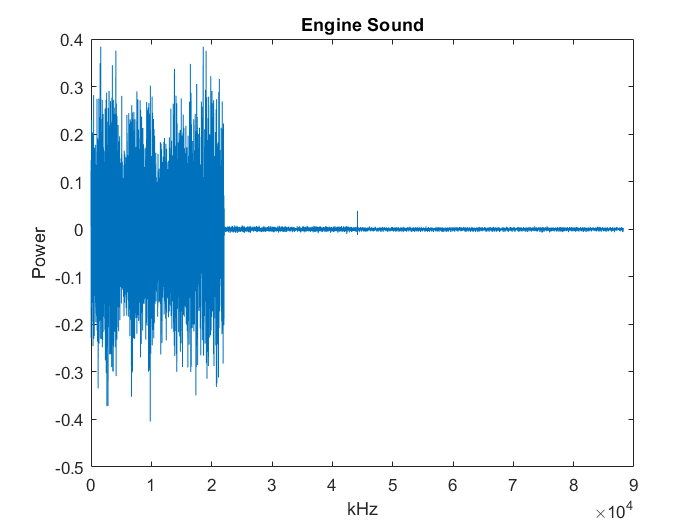

%Analysing the background noise
level = 2;
bare = audioread('enginetest.wav');
engtest = wavedec(bare,level,'rbio2.8');
plot (engtest)
title ('Engine Sound')
xlabel ('kHz'); ylabel ('Power');

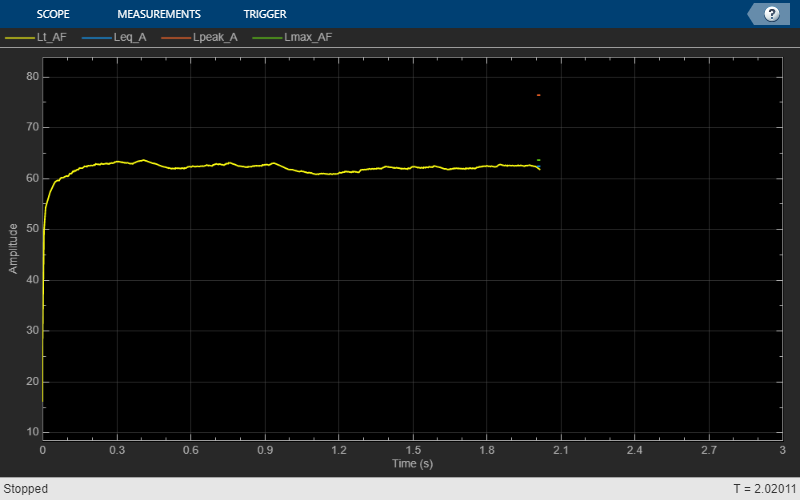

%Find the A-weighted sound pressure level of background noise
source = dsp.AudioFileReader('enginetest.wav');
fs = source.SampleRate;

player = audioDeviceWriter('SampleRate',fs);

scope  = timescope('SampleRate',fs, ...
    'TimeSpanOverrunAction','Scroll', ...
    'TimeSpanSource','Property','TimeSpan',3,'ShowGrid',true, ...
    'YLimits',[20 110],'AxesScaling','Auto', ...
    'ShowLegend',true,'BufferLength',4*3*fs, ...
    'ChannelNames', ...
    {'Lt_AF','Leq_A','Lpeak_A','Lmax_AF'}, ...
    'Name','Sound Pressure Level Meter');

SPL = splMeter('TimeWeighting','Fast', ...
    'FrequencyWeighting','A-weighting', ...
    'SampleRate',fs, ...
    'TimeInterval',2);
while ~isDone(source)
    x = source();
    player(x);
    [Lt,Leq,Lpeak,Lmax] = SPL(x);
    scope([Lt,Leq,Lpeak,Lmax])
end

release(source)
release(player)
release(SPL)
release(scope)

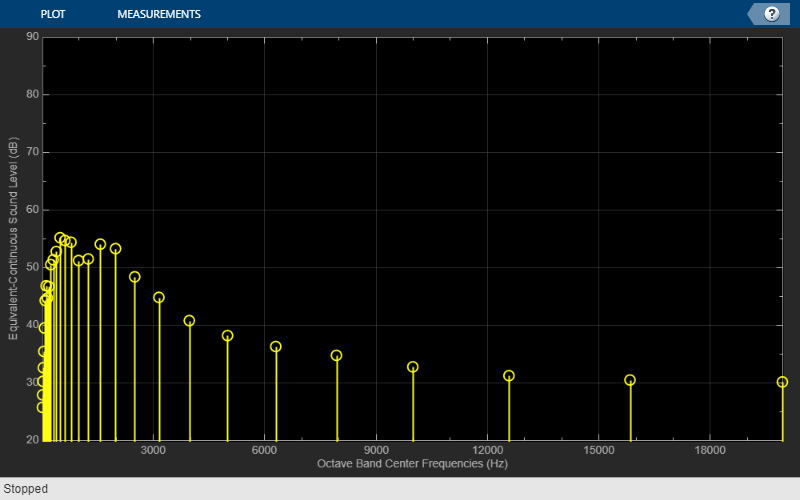

%Find the Sound Pressure level of background noise
source1 = dsp.AudioFileReader('enginetest.wav');
fs = source1.SampleRate;

player = audioDeviceWriter('SampleRate',fs);

SPL = splMeter( ...
    'Bandwidth','1/3 octave', ...
    'SampleRate',fs);
centerFrequencies = getCenterFrequencies(SPL);

scope  = dsp.ArrayPlot(...
    'XDataMode','Custom', ...
    'CustomXData',centerFrequencies, ...
    'XLabel','Octave Band Center Frequencies (Hz)', ...
    'YLabel','Equivalent-Continuous Sound Level (dB)', ...
    'YLimits',[20 90], ...
    'ShowGrid',true, ...
    'Name','Sound Pressure Level Meter');
LeqPrevious = zeros(size(centerFrequencies));
while ~isDone(source1)
    x = source1();
    player(x);
    [~,Leq] = SPL(x);

    for i = 1:size(Leq,1)
        if LeqPrevious ~= Leq(i,:)
            scope(Leq(i,:)')
            LeqPrevious = Leq(i,:);
        end
    end

end

release(source1)
release(player)
release(SPL)
release(scope)

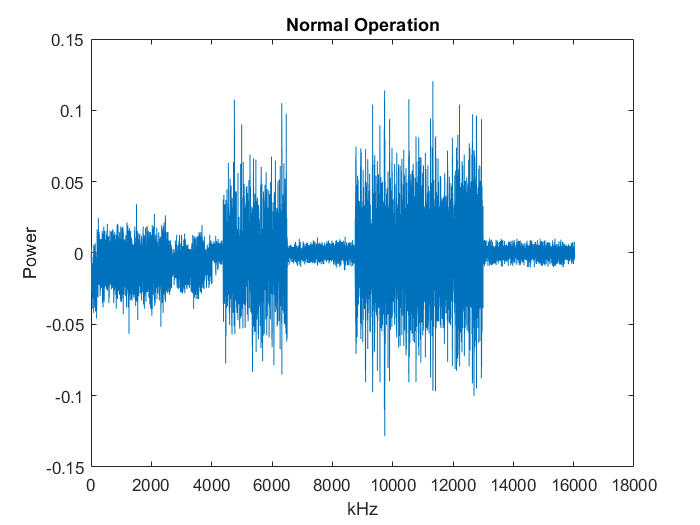

%Analysing the audio signal without any casing
level = 2;
bare = audioread("C:\Users\leere\Documents\MATLAB\test new\bare\bare1.wav");
bare1 = wavedec(bare,level,'rbio2.8');
plot (bare1)
title ('Normal Operation')
xlabel ('kHz'); ylabel ('Power');

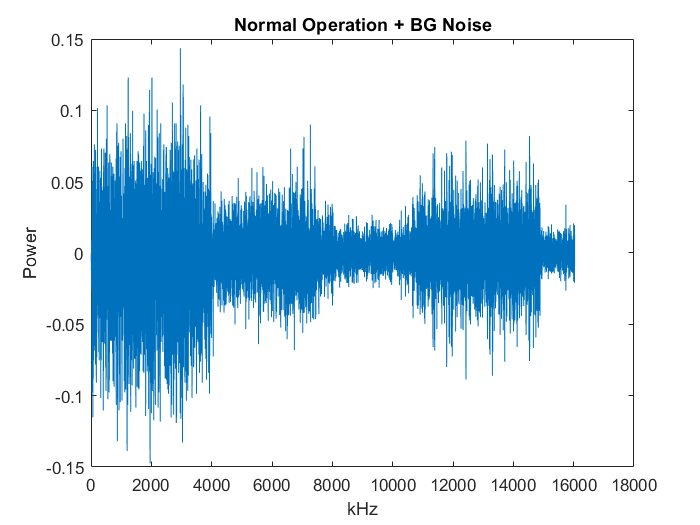

%Analysing the signal with background noise
level =2;
barewbg = audioread("C:\Users\leere\Documents\MATLAB\test new\barewbg\barewbg1.wav");
barewbg1 = wavedec(barewbg,level,'rbio2.8');
plot (barewbg1)
title ('Normal Operation + BG Noise')
xlabel ('kHz'); ylabel ('Power');

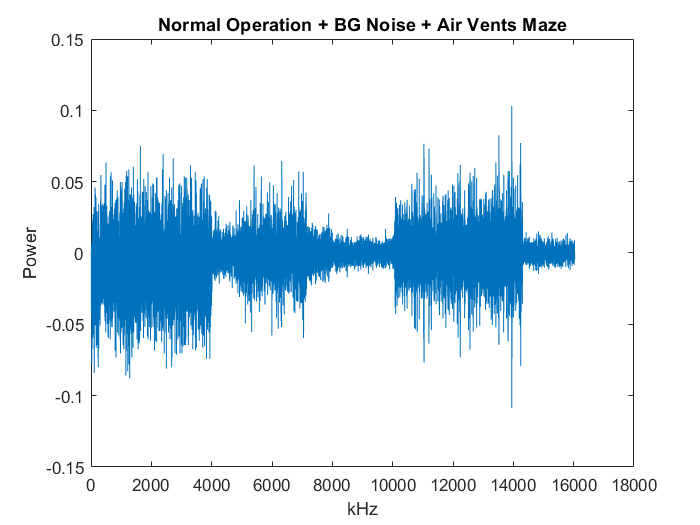

%Analysing the signal with background noise and padded ventilation
level = 2;
 PaddedVent = audioread("C:\Users\leere\Documents\MATLAB\test new\ventpad\ventpad11.wav");
Paddedvent1 = wavedec(PaddedVent,level,'rbio2.8');
plot (Paddedvent1)
title ('Normal Operation + BG Noise + Air Vents Maze')
xlabel ('kHz'); ylabel ('Power');

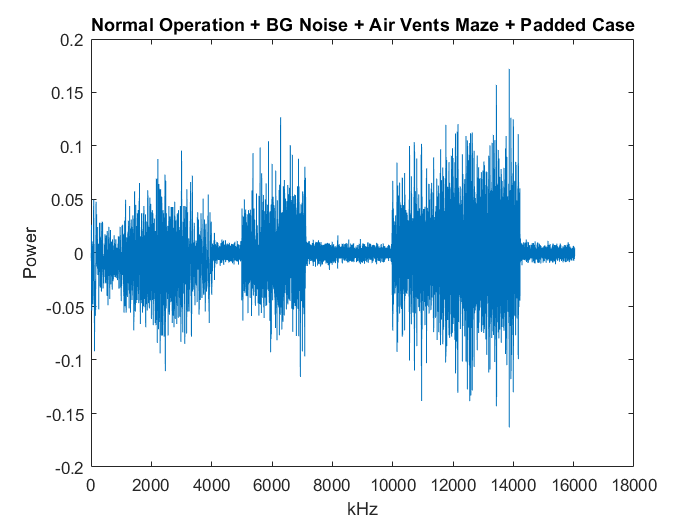

%Analysing the signal with background noise and padded ventilation and
%padded exterior
level =2;
outsidepadded = audioread("C:\Users\leere\Documents\MATLAB\test new\outpad\outpad1.wav");
outsidepadded1 = wavedec(outsidepadded,level,'rbio2.8');
plot (outsidepadded1)
title ('Normal Operation + BG Noise + Air Vents Maze + Padded Case')
xlabel ('kHz'); ylabel ('Power');

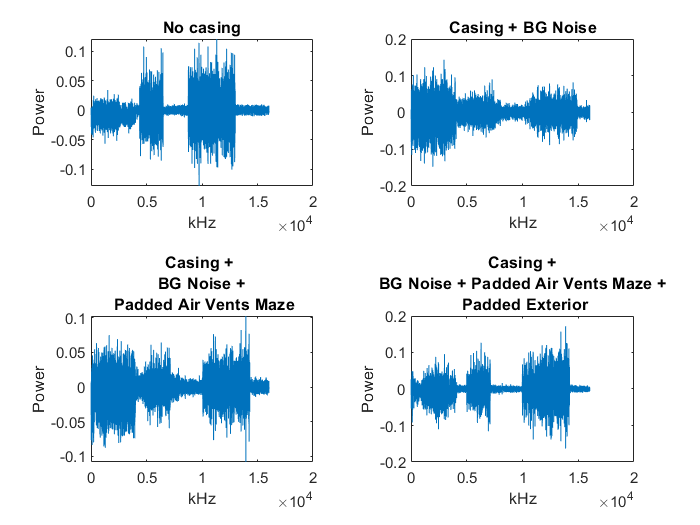

%Plot all four signals in one graph
t = tiledlayout(2,2); % Requires R2019b or later
nexttile
plot(bare1)
title ('No casing')
xlabel ('kHz'); ylabel ('Power');
nexttile
plot(barewbg1)
title ('Casing + BG Noise')
xlabel ('kHz'); ylabel ('Power');
nexttile
plot(Paddedvent1)
title ({'Casing + ', 'BG Noise +',' Padded Air Vents Maze'})
xlabel ('kHz'); ylabel ('Power');
nexttile
plot(outsidepadded1)
title ({'Casing +', 'BG Noise + Padded Air Vents Maze +',' Padded Exterior'})
xlabel ('kHz'); ylabel ('Power');

%Data store
rng(1)
datafoldernew = "C:\Users\leere\Documents\MATLAB\test new";

adsnew = audioDatastore(datafoldernew, ...
    'IncludeSubfolders',true, ...
    'FileExtensions','.wav', ...
    'LabelSource','foldernames');

%Create directory to store spectograms
datafolder_scallogramnew = "datafoldernew/structurenew";
catego=categories(adsnew.Labels);
for i = 1:1:length(catego)
    imgLoc = fullfile(datafolder_scallogramnew,char(catego{i}));
    mkdir(imgLoc)
end

helperCreateRGBNEW(adsnew,datafolder_scallogramnew);

%imageDatastore
normalop = imageDatastore("C:\Users\leere\Documents\MATLAB\Examples\R2021a\deeplearning_shared\ClassifyLargeMultiresolutionImagesUsingDeepLearningExample\datafoldernew\structurenew\bare",...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');
normalop_bg = imageDatastore("C:\Users\leere\Documents\MATLAB\Examples\R2021a\deeplearning_shared\ClassifyLargeMultiresolutionImagesUsingDeepLearningExample\datafoldernew\structurenew\barewbg",...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');
Paddedvent = imageDatastore("C:\Users\leere\Documents\MATLAB\Examples\R2021a\deeplearning_shared\ClassifyLargeMultiresolutionImagesUsingDeepLearningExample\datafoldernew\structurenew\ventpad",...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');
paddedcase = imageDatastore("C:\Users\leere\Documents\MATLAB\Examples\R2021a\deeplearning_shared\ClassifyLargeMultiresolutionImagesUsingDeepLearningExample\datafoldernew\structurenew\outpad",...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

%Classify new data stores
[r1] = classify(net,normalop);
[r2] = classify(net,normalop_bg);
[r3] = classify(net,Paddedvent);
[r4] = classify(net,paddedcase);

function helperCreateRGBNEW(adsnew,datafolder_scallogramnew)

for i = 1:length(adsnew.Files)
    clearvars sig
   
    level=2;
    signew = audioread(adsnew.Files{i});
    cfsnew = abs(wavedec(signew(:),level,'rbio2.8'));
   
    im = ind2rgb(im2uint8(rescale(cfsnew)),jet(128));   
    imgLoc = fullfile(datafolder_scallogramnew,char(adsnew.Labels(i)));
    imFileName = strcat(char(adsnew.Labels(i)),'_',num2str(i),'.jpg');
    imwrite(imresize(im,[224 224]),fullfile(imgLoc,imFileName));
end
end